### **AuE 8930- Project**

### **Group 2**

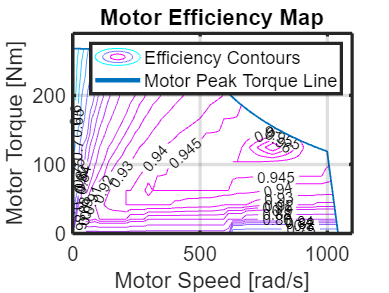

%initialisation
clear all;
close all;

%%% Fuel Cell Parameters
Fuel_Cell.OC_Voltage = 65;
Fuel_Cell.Collapse_Current = 200;
Fuel_Cell.Exchange_Current = 80;
Fuel_Cell.Resistance = 0.05;
Fuel_Cell.Tafel_Slope = 023;
Fuel_Cell.pH2_nom = 1.5e5;
Fuel_Cell.pAir_nom = 1.0e5;
Fuel_Cell.Cooling_Area = 1e-4;
Fuel_Cell.Cooling_Alpha = 150;
Fuel_Cell.Cooling_Theta = 293.15;
Fuel_Cell.Theta_Init = 273.15+10; 

%%% Battery Parameters
Battery.Unom = 300;
Battery.U1 = 200;
Battery.Qnom = 500;
Battery.Q1 = 250;
Battery.Resistance = 0.05;
Battery.Uinit = 250;

%%% Electric Motor
Electric_Motor.Speed = (2*pi*50/4)*2;
Electric_Motor.TorqueMax = 300;
Electric_Motor.TorqueMin = -50;
Electric_Motor.Torque = 300;
Electric_Motor.Power = 60; %kW

Generator_Eff = 0.95;

cla reset
%Motor Model
load Motor_Data.mat  % needed for the motor_inverter subsystem to be properly defined
Generator_Eff = 0.95;

cla reset
%Motor Model
load Motor_Data.mat
load CB.mat;
load CF.mat
load PB.mat;
load PC.mat;
load ss.mat;
% needed for the motor_inverter subsystem to be properly defined
%% plot the efficiency map
% define some efficiency values for which to create contour lines
eta = [0.97 0.965 0.96 0.955 0.95 0.945 0.94 0.93 0.92 0.91 0.9 0.88 0.86 0.84 0.82 0.8 0.75 0.7 0.65 0.6 0.55 0.5];

% Create a contour plot of the efficiency map:
%   EM_Efficiency_Map is a 2D lookup table with efficiency values for given
%      rotational speed and torques corresponding to the scales below
%   EM_Omega_Map represents the speed in rad/s
%   EM_Torque_Map represents the torque in Nm
[cc,h] = contour(EM_Omega_Map,EM_Torque_Map,EM_Efficiency,eta);
clabel(cc,h);
grid on

%% overlay the maximum torque curve on the same plot
%   EM_Torque_Max represents the maximum torque in Nm
%   EM_Omega_Max represents the corresponding speed in rad/s
hold on
% plot(RPM_sim,Torque_sim,'k.')
plot(EM_Omega_Max,EM_Torque_Max,'linewidth',3)
colormap(cool)
hold off

% The map extends beyond the rated range for the motor.  We therefore plot
% the maximum torque values and white out the portion of the map that is
% invalid 
large = 1e6;
xp = [EM_Omega_Max EM_Omega_Max(end) large large 0];
yp = [EM_Torque_Max 0 0 large large];
patch(xp,yp,'white','Edgecolor','white');
axis([0 max(EM_Omega_Map)+50 0 max(EM_Torque_Map)+20])

% Show the metadata to make the plot understandable
xlabel('Motor Speed [rad/s]')
ylabel('Motor Torque [Nm]')
title('Motor Efficiency Map')
legend('Efficiency Contours','Motor Peak Torque Line','location','northeast')

%Battery model

load HW5_data.mat;
% %% Battery parameters
% batt.num_cells = 81*2;    % total number of cells
% batt.num_cell_series = 81;  % number of cells in series
% batt.num_module_parallel = 2;   % number of modules in parallel
% batt.volt_nom = 3.6;    % nominal voltage in V
% batt.volt_max = 3.9;    % max voltage in V
% batt.volt_min = 3.2;    % min voltage in V
% batt.curr_chg_max = -15.9821;  % max charging current in A
% batt.curr_dis_max = 21.75;     % max discharging current in A
% batt.soc_max = 0.8;     % max SoC
% batt.soc_min = 0.3;     % min SoC
% batt.soc_init = 0.75;     % initial SoC
% batt.op_temp = 30;      % deg C
% batt.cap_max.cap_max = batt.cap_max.cap_max*(32/6)
% Converter requirements
% batt_chg_v = 320; % Step-up voltage in [V]
% mot_out_v = 260; % Step-down voltage in [V]
% Step_up_eff = 0.96; % Step-up power efficiency
% Step_down_eff = 0.95; % Step-down power efficiency
% Conv.I=0:10:200;
% Conv.Boost_Eff=[0.1 0.6 0.78 0.84 0.88 0.90 0.92 0.945 0.94 0.94 0.93 0.92 0.91 0.90 0.89 0.88 0.87 0.86 0.85 0.84 0.83];
% Conv.Buck_Eff=[0.1 0.6 0.78 0.84 0.88 0.90 0.92 0.935 0.93 0.93 0.92 0.91 0.90 0.90 0.89 0.88 0.87 0.86 0.85 0.84 0.83];

% Vehicle model
% Initialize vehicle parameters
mass = 1632; % kg, Curb weight of vehicle converted from lbs
mu = 1; % friction coefficient*
r_tire = 0.43; % tire radius in [m]
Cd= 0.75; % the drag coefficient
frr = 0.01; % the tire rolling resistance coefficient*
rho_air = 1.26; % the density of air in [kg/m3]
Af = 2.32; % the cross-sectional area in [m2]
ratio_fd = 5; % Overall gear ratio including the final drive
eff_trans = 0.98; % transmission inefficiency
batt_cap = 64; % electric charge storage capacity [Ah]
batt_volt = 300; % battery voltage in [V]
WB = 57.7*0.0254; % m, Wheelbase of the vehicle converted from in
W_f = 0.4*mass; % Front weight bias from the Weight Distribution
W_r = 0.6*mass; % Rear weight bias from the Weight Distribution
CG = 20*0.0254; % m, Height of centre of gravity of vehicle


% feedback control gains for Task 4
Kp = 1;
Ki = 0.2;

% some constants
g = 9.81; % graviational acceleration in [m/s2]
mps2kph = 3.6; % multiplication factor to convert from [m/s] to [km/h]

%4WD Traction calculations
Ft_m = mu*mass*g/1000; % kN, Maximum Traction Force allowed by the tires
Accl_Max = (Ft_m*1000)/mass; % ms^-2, Maximum Acceleration or Deceleration allowed by the tires
a = W_r*WB; % m, distance of CG from Front axle
b = W_f*WB; % m, distance of CG from Rear axle
Ft_f_accl = (mu*mass*((g*b)-(CG*Accl_Max)))/(a+b); % N, Maximum Traction Force allowed by the Front Axle
Ft_r_accl = (mu*mass*((g*a)+(CG*Accl_Max)))/(a+b); % N, Maximum Traction Force allowed by the Rear Axle
Ft_f_decl = -1*(mu*mass*((g*b)+(CG*Accl_Max)))/(a+b); % N, Maximum Traction Force allowed by the Front Axle
Ft_r_decl = -1*(mu*mass*((g*a)-(CG*Accl_Max)))/(a+b); % N, Maximum Traction Force allowed by the Rear Axle

% simulation run
% t_end = 200;
% exampleResult = sim('AuE_6610_Project_Accl_MaxSpd_Model',t_end);
%Result_US06 = sim('AuE_6610_Project_US06',600);
%high_trans = readtable("High_Spd_Transient.xlsx");
%high_trans_speed = table2array(high_trans);
out = sim("AuE8930_G2.slx");

Program interruption (Ctrl-C) has been detected.

% cla reset
% %Motor Model
% load Motor_Data.mat  % needed for the motor_inverter subsystem to be
% properly defined 
% %% plot the efficiency map
% % define some efficiency values for which to create contour lines
% eta = [0.97 0.965 0.96 0.955 0.95 0.945 0.94 0.93 0.92 0.91 0.9 0.88 0.86 0.84 0.82 0.8 0.75 0.7 0.65 0.6 0.55 0.5];
% EM_Omega_Map = EM_Omega_Map*(1256.637061/1047);
% EM_Omega_Max = EM_Omega_Max*(1256.637061/1047);
% EM_Torque_Map = EM_Torque_Map*(215/270);
% EM_Torque_Max = EM_Torque_Max*(215/270);
% 
% % Create a contour plot of the efficiency map:
% %   EM_Efficiency_Map is a 2D lookup table with efficiency values for given
% %      rotational speed and torques corresponding to the scales below
% %   EM_Omega_Map represents the speed in rad/s
% %   EM_Torque_Map represents the torque in Nm
% [cc,h] = contour(EM_Omega_Map,EM_Torque_Map,EM_Efficiency,eta);
% clabel(cc,h);
% grid on
% 
% %% overlay the maximum torque curve on the same plot
% %   EM_Torque_Max represents the maximum torque in Nm
% %   EM_Omega_Max represents the corresponding speed in rad/s
% hold on
% % plot(RPM_sim,Torque_sim,'k.')
% plot(EM_Omega_Max,EM_Torque_Max,'linewidth',3)

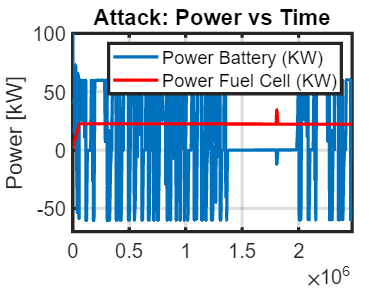

set(0,'defaultAxesLineWidth',2.2)
set(0,'defaultAxesFontSize',14)
set(0,'defaultLineLinewidth',2.2)
set(0,'defaultscatterLinewidth',1.5)
set(0,'DefaultAxesBox','on')
set(0,'DefaultAxesXGrid','on')
set(0,'DefaultAxesYGrid','on')
plot(PowerBatt)
hold on
plot(PowerFC,'r')
hold off
ylabel("Power [kW]")
xlim([0,2474000])
ylim([-70,100])
legend("Power Battery (KW)","Power Fuel Cell (KW)")
title("Attack: Power vs Time")

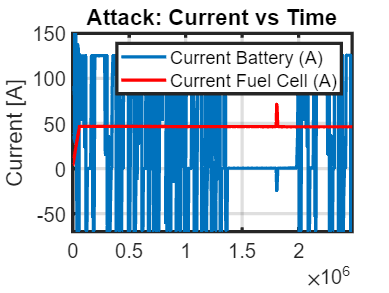

plot(CurrBatt)
hold on
plot(CurrFC,'r')
hold off
xlim([0,2474000])
ylim([-70,150])
ylabel("Current [A]")
legend("Current Battery (A)","Current Fuel Cell (A)")
title("Attack: Current vs Time")

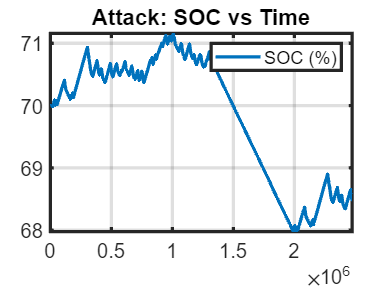

plot(SOC)
legend("SOC (%)")
title("Attack: SOC vs Time")
xlim([0,2474000])

plot(out.reference_speed)

Unable to resolve the name 'out.reference_speed'.

hold on
plot(out.vehicle_speed,'r--')
hold off
xlim([0,2474000])
ylim([-1,30])
ylabel("Speed [m/s]")
legend("Reference Speed (m/s)","Vehicle Speed (m/s)")
title("Attack: Reference Speed vs Vehicle Speed")
